## 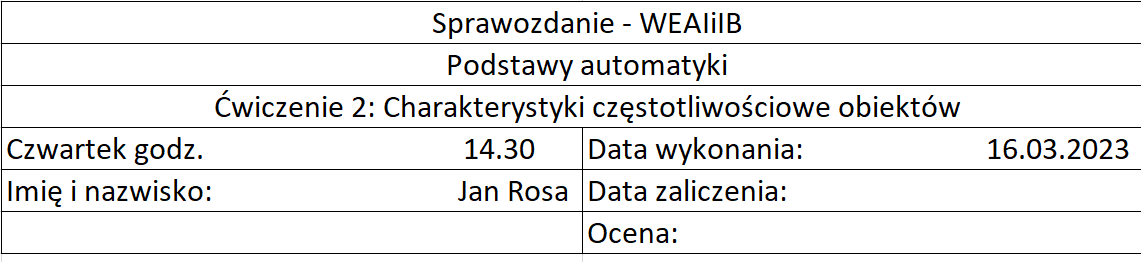

### Cel Ćwiczenia

Celem ćwiczenia jest zapoznanie się z charakterystykami częstotliwościowymi podstawowych obiektów dynamicznych. Podczas ćwiczenia należy zbadać charakterystyki częstotliwościowe tych samych obiektów, które były badane podczas poprzedniego ćwiczenia. Badane będą następujące dwa podstawowe typy charakterystyk częstotliwościowych:

• **charakterystyka częstotliwościowa amplitudowo - fazowa**. Jest ona wykreślana na płaszczyźnie zespolonej i jest ona miejscem geometrycznym końca wektora, którego współrzędnymi są: Re( G(jω)) oraz Im ( G(jω)) przy zmianie pulsacji ω w zakresie od zera do nieskończoności, gdzie G(jω) jest transmitancją widmową obiektu.

** • charakterystyka częstotliwościowa logarytmiczna modułu i fazy**. Są to wykresy modułu i fazy transmitancji widmowej G(jω) w funkcji pulsacji ω , przy czym zmienna niezależna ω jest podana w skali logarytmicznej (tj. w równych odstępach np. 0.1 1 10 ... ). Moduł transmitancji jest podawany w decybelach [dB], czyli jest on równy 20 log( | G(jω)| ), faza jest podawana w stopniach.

Podczas ćwiczenia należy zbadać oba typy charakterystyk dla podstawowych obiektów omówionych we wprowdzeniu. Są one następujące:

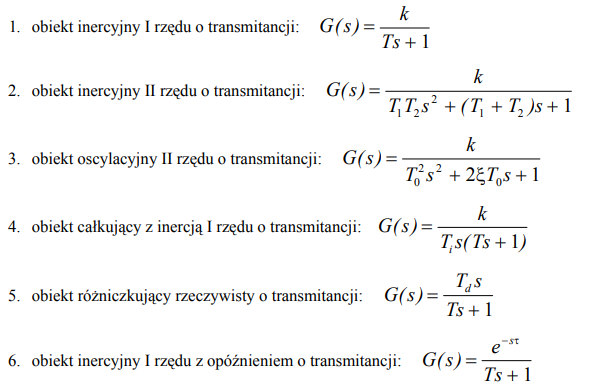

Zapis transmitancji w MATLAB-ie. Transmitancja w MATLAB-ie jest reprezentowana przez 2 wektory, zawierające współczynniki jej licznika i mianownika. Sposób zapisu w MATLAB-ie obiektów wymienionych powyżej jest podany w poniższej tabeli. 

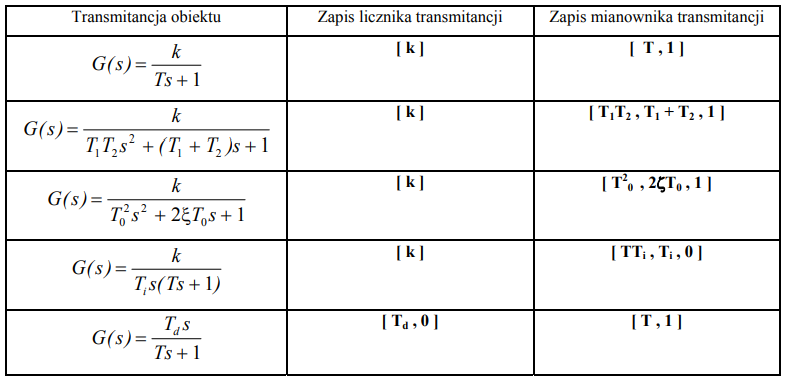

### Wykonanie ćwiczenia

W czasie ćwiczenia należy wykonać komplety charakterystyk amplitudowo-fazowych oraz logarytmicznych modułu i fazy dla każdego z obiektów rozważanych w poprzednim ćwiczeniu, parametry obiektów należy wziąć z poprzedniego ćwiczenia. Należy to zrobić tak , aby na wspólnym wykresie znalazły się charakterystyki dla kilku różnych zestawów parametrów obiektu.

### Obiekt inercyjny I rzędu

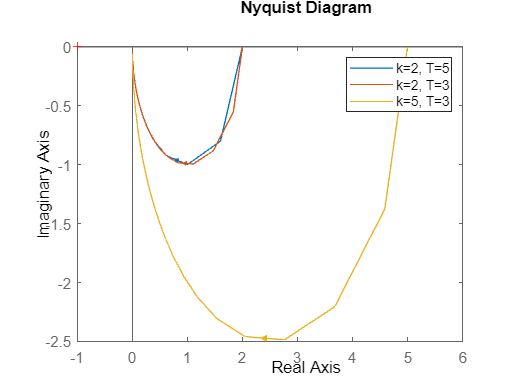

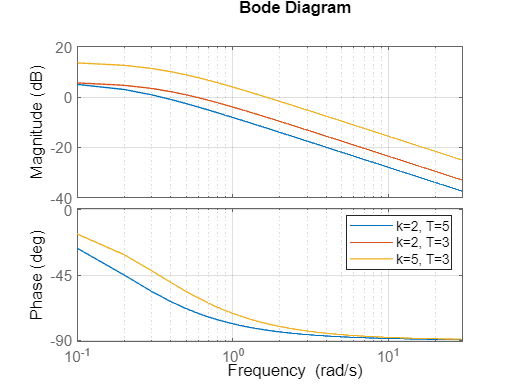

k = 2;
T = 5;
obiekt11 = tf([0, k], [T, 1]);

k = 2;
T = 3;
obiekt12 = tf([0, k], [T, 1]);

k = 5;
T = 3;
obiekt13 = tf([0, k], [T, 1]);

wykres(obiekt11, obiekt12, obiekt13, "k=2, T=5", "k=2, T=3", "k=5, T=3", 0:0.1:30)

Symulowany obiekt zachowuje się typowo a skutki zmian parametrów są przewidywalne, tj k odpowiada za wzmocnienie a T za opóźnienie

### Obiekt inercyjny II rzędu

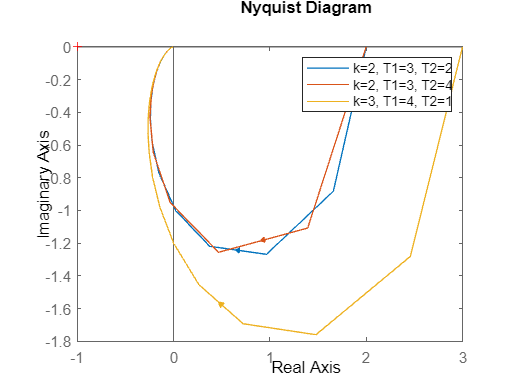

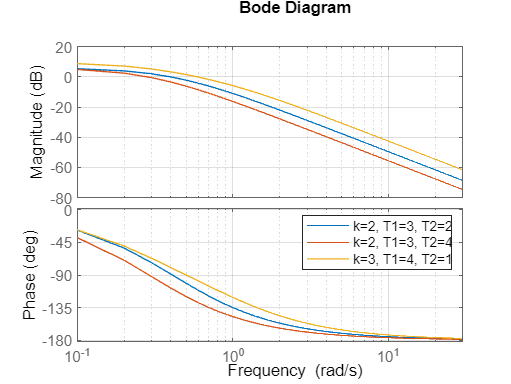

T1 = 2;
T2 = 3;
k = 2;
obiekt21 = tf([0,0,k], [T1*T2, T1+T2, 1]);
k = 2;
T1 = 3;
T2 = 4;
obiekt22 = tf([0,0,k], [T1*T2, T1+T2, 1]);
k = 3;
T1 = 4;
T2 = 1;
obiekt23 = tf([0,0,k], [T1*T2, T1+T2, 1]);

wykres(obiekt21, obiekt22, obiekt23, "k=2, T1=3, T2=2", "k=2, T1=3, T2=4", "k=3, T1=4, T2=1", 0:0.1:30)

Symulowany obiekt zachowuje się typowo a skutki zmian parametrów są przewidywalne, tj k odpowiada za wzmocnienie a T1 i T2 za parametry dwóch zbiorników energii

### Obiekt inercyjny II rzędu oscylacyjny

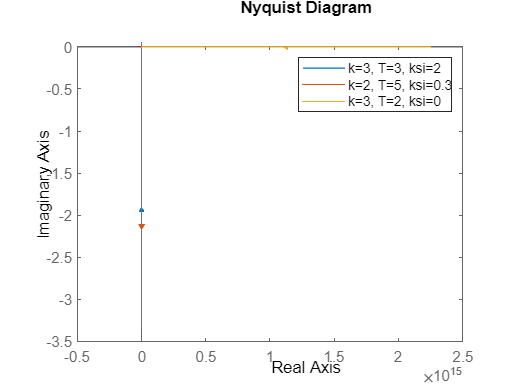

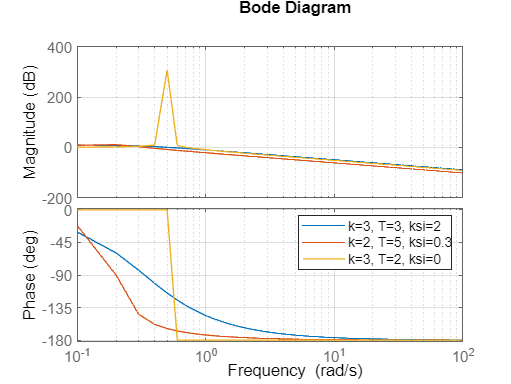


k = 3;
T = 3;
ksi = 0.9;
obiekt31 = tf([0,0,k], [T^2, 2*ksi*T, 1]);

k = 2;
T = 5;
ksi = 0.3;
obiekt32 = tf([0,0,k], [T^2, 2*ksi*T, 1]);

k = 1;
T = 2;
ksi = 0;
obiekt33 = tf([0,0,k], [T^2, 2*ksi*T, 1]);

wykres(obiekt31, obiekt32, obiekt33, "k=3, T=3, ksi=2", "k=2, T=5, ksi=0.3","k=3, T=2, ksi=0", 0:0.1:100)

Symulowany obiekt zachowuje się typowo a skutki zmian parametrów są przewidywalne, tj k odpowiada za wzmocnienie, amplitudę drgań, T za opóżnienie/częstość drgań, a ksi za zanikanie/tłumienie oscylacji

### Obiekt całkujący rzeczywisty z inercją

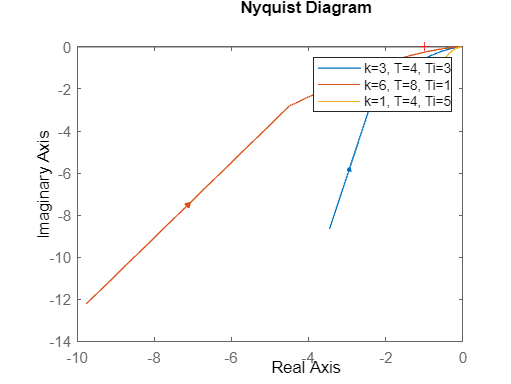

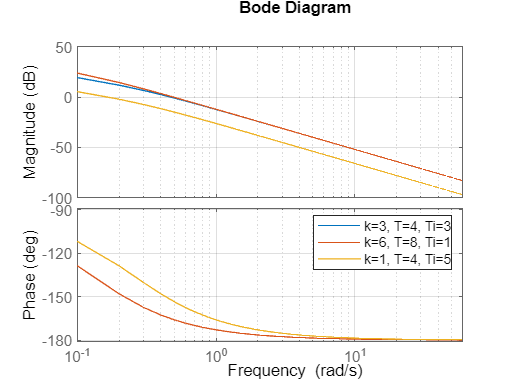

k = 3;
T = 4;
Ti = 3;
obiekt41 = tf([0,0,k], [T*Ti, Ti, 0]);

k = 2;
T = 8;
Ti = 1;
obiekt42 = tf([0,0,k], [T*Ti, Ti, 0]);

k = 1;
T = 4;
Ti = 5;
obiekt43 = tf([0,0,k], [T*Ti, Ti, 0]);

wykres(obiekt41, obiekt42, obiekt43, "k=3, T=4, Ti=3", "k=6, T=8, Ti=1", "k=1, T=4, Ti=5", 0:0.1:60)

Symulowany obiekt zachowuje się typowo a skutki zmian parametrów są przewidywalne, tj k odpowiada za wzmocnienie, T za opóźnienie a Ti za czas całkowania im Ti większy tym całka mniej dokładna

### Obiekt różniczkujący rzeczywisty z inercją

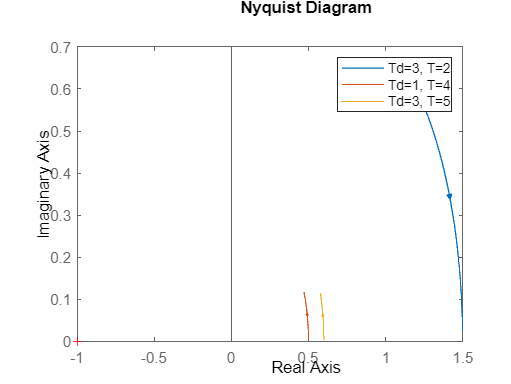

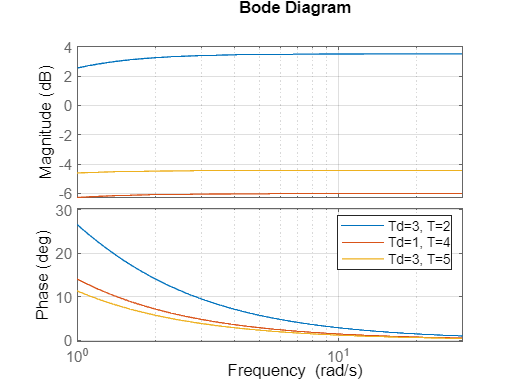


Td = 3;
T = 2;
obiekt51 = tf([Td, 0], [T, 1]);

Td = 2;
T = 4;
obiekt52 = tf([Td, 0], [T, 1]);

Td = 3;
T = 5;
obiekt53 = tf([Td, 0], [T, 1]);

wykres(obiekt51, obiekt52, obiekt53, "Td=3, T=2", "Td=1, T=4","Td=3, T=5", 1:0.1:30)

Symulowany obiekt zachowuje się typowo a skutki zmian parametrów są przewidywalne, tj k odpowiada za wzmocnienie, T za opóźnienie a Td za czas różniczkowania im Td mniejszy tym różniczkowanie mniej dokładne

### Obiekt inercyjny I rzędu z opóźnieniem

Aby opóżnienie mogło być zrealizowane wydajnie w programie Matlab należy je sprowadzić do wielomianowego przybliżenia jakim jest aproksymacja Padego. Następnie należy polaczyć obiekty w przestrzeni operatorowej szeregowo aby otrzymać pożądany obiekt inercyjny z opóżnieniem. 

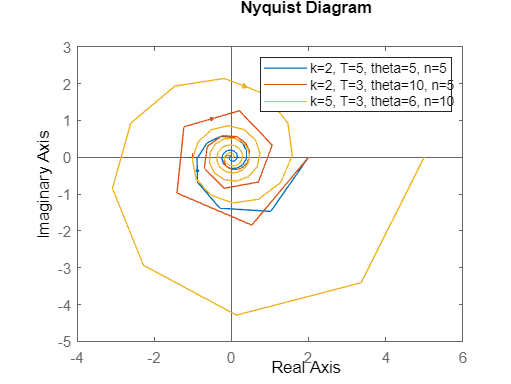

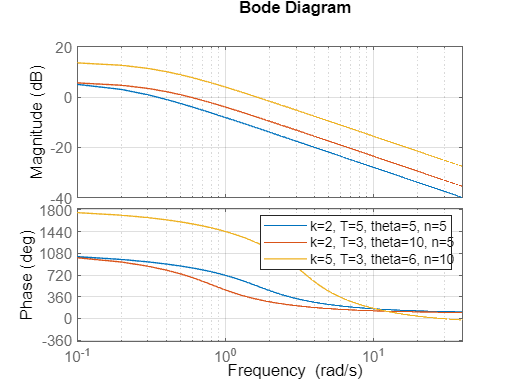

theta = 5;
n = 5;
[licz, mian] = pade(theta, n);
opoz1 = tf(licz, mian);
theta = 10;
n = 5;
[licz, mian] = pade(theta, n);
opoz2 = tf(licz, mian);
theta = 5;
n = 10;
[licz, mian] = pade(theta, n);
opoz3 = tf(licz, mian);


obiekt61 = series(opoz1, obiekt11);
obiekt62 = series(opoz2, obiekt12);
obiekt63 = series(opoz3, obiekt13);

wykres(obiekt61, obiekt62, obiekt63, "k=2, T=5, theta=5, n=5", "k=2, T=3, theta=10, n=5", "k=5, T=3, theta=6, n=10", 0:0.1:40)

Odwzorowanie opóźnienia jest dobre w wypadku odpowiedzi na wymuszenie skokowe, natomiast odpowiedź na wymuszenie impulsowe jest wyrażnie zniekształcona

### Funkcja Wykres

function [] = wykres(obiekt1, obiekt2, obiekt3, label1, label2, label3, t)
figure()
plotoptions = nyquistoptions('cstprefs');
plotoptions.ShowFullContour = 'off';
nyquist(obiekt1,obiekt2, obiekt3, t, plotoptions)
legend(label1,label2, label3)
figure()
bode(obiekt1, obiekt2, obiekt3, t)
grid on;
legend(label1, label2, label3)
end

### Wnioski

Przedstawione zadanie nie sprawiło żadnych trudności. Najtrudniejszą jego częścią było usunięcie ujemnych częstotliwości z wykresu Nyquista. Do zmniejszenia ilości kodu zastosowałem krótką funkcję wykreślającą wykresy. Obiekty zasymulowane przez matlaba odpowiadają przewidywaniom jedyne problemy sprawia aproksymacja padego która na wykresie nyquista jest nieskończoną spiralą która uwidacznia dyskretne obliczenia komputera tj wykres robi się kanciasty.